# HAMR-6 SE(2) locomotion study

## 3D reconstruction of trajectory and kinematics

The goal of this section is to take the properties of HAMR reconstruct it in 3D and add the trajectory of the robot to it. Here's a marked up top view of HAMR-6 and that will be the subject of 3D reconstruction study. **All units are in mm.**

### Respecting form-factor symmetry

In this subsection, we shall use our bounding box measurements and respect the symmetry of the design. This would mean, as shown in the top-view, the bounding boxes shall have equal opposing sides.

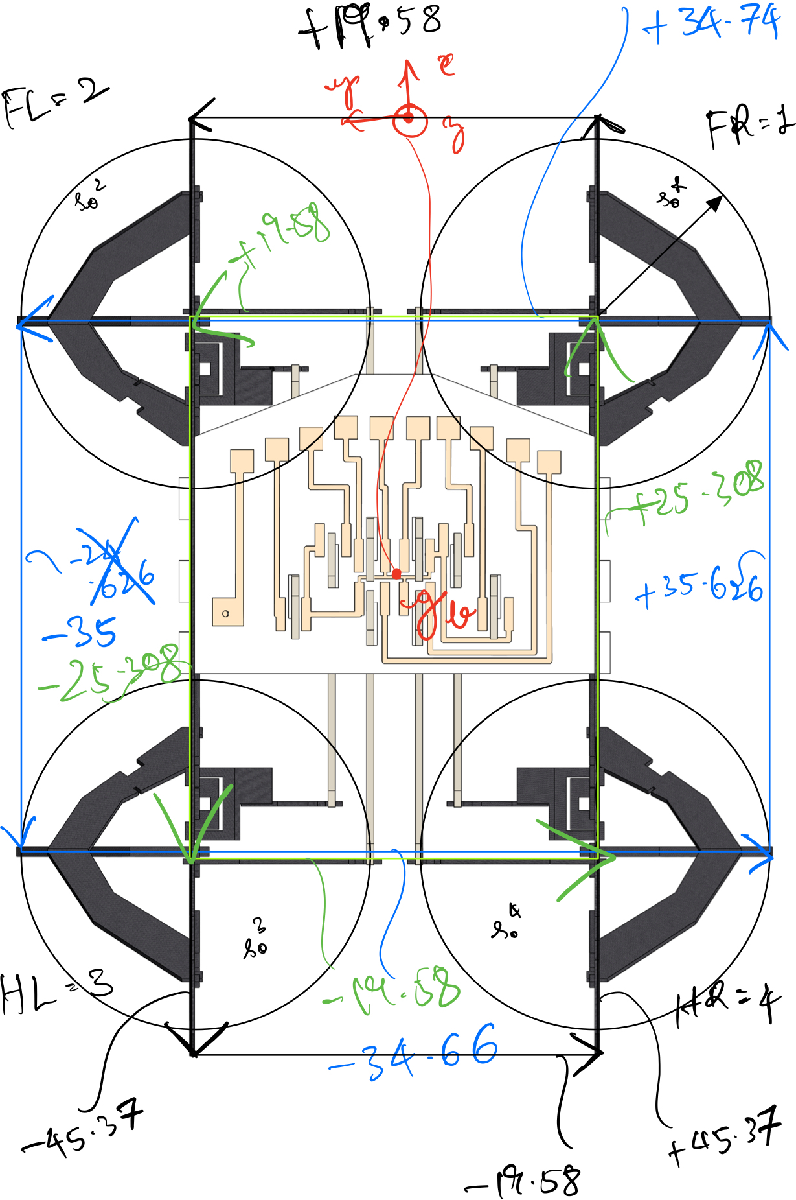

There and 3 bounding boxes above-- the green one connects the bases of each spherical five-bar transmission (SFB), the blue one connects the feet-tips, and the black one connects the tips of the body excluding the legs. These boxes are at different levels, and hence we need to handle that to get the right 3D reconstruction. Hence, these bounding boxes are defined as a set of cyclic vectors forming a closed shape (boxes in the quadrupedal case)-- the vectors are defined in a global rest frame that is aligned with the body frame before the motion begins. Assume the initial point of the first vector (tail) to be the origin for this set of vectors. We shall exploit the fact that all the these bounding boxes are centered around the body frame of the robot. NOTE: THE BOXES ARE AT DIFFERENT Z-LEVELS. This must be accounted for when doing the transformations.

Let's first round off all quantities to 3 significant digits instead of 4 significant digit measurement.

% add utilities function toe the path
addpath 'Data'\ 'Utility Functions'\;

% foot bounds ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
foot_bound = [[0, 34.74, 0]; [-35, 0, 0]; [0, -34.66, 0]; [35.626, 0, 0]]

foot_bound =          0   34.7400         0
  -35.0000         0         0
         0  -34.6600         0
   35.6260         0         0


foot_bound = boundboxmean(foot_bound, true) % true because it is designed to be a square

foot_bound =      0    35     0
   -35     0     0
     0   -35     0
    35     0     0


% hip bounds ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
hip_bound = [[0, 19.58, 0]; [-25.308, 0, 0]; [0, -19.58, 0]; [25.308, 0, 0]]

hip_bound =          0   19.5800         0
  -25.3080         0         0
         0  -19.5800         0
   25.3080         0         0


hip_bound = boundboxmean(hip_bound, false)

hip_bound =          0   19.6000         0
  -25.3000         0         0
         0  -19.6000         0
   25.3000         0         0


% body w/o leg bounds ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
% there's a top and a bottom version for this bounding box and this will be addressed in the next section.
bodywoleg_bound = [[0, 19.58, 0]; [-45.37, 0, 0]; [0, -19.58, 0]; [45.37, 0, 0]]

bodywoleg_bound =          0   19.5800         0
  -45.3700         0         0
         0  -19.5800         0
   45.3700         0         0


bodywoleg_bound = boundboxmean(bodywoleg_bound, false)

bodywoleg_bound =          0   19.6000         0
  -45.4000         0         0
         0  -19.6000         0
   45.4000         0         0


### Translational transformations to body center

Now, let's compute the transforms from the body frame to the frames of interest-- we shall break down transformations into translations and rotations. Here's an isometric view of the 3D reconstruction of the robot we need and also the z change between various bounding boxes.

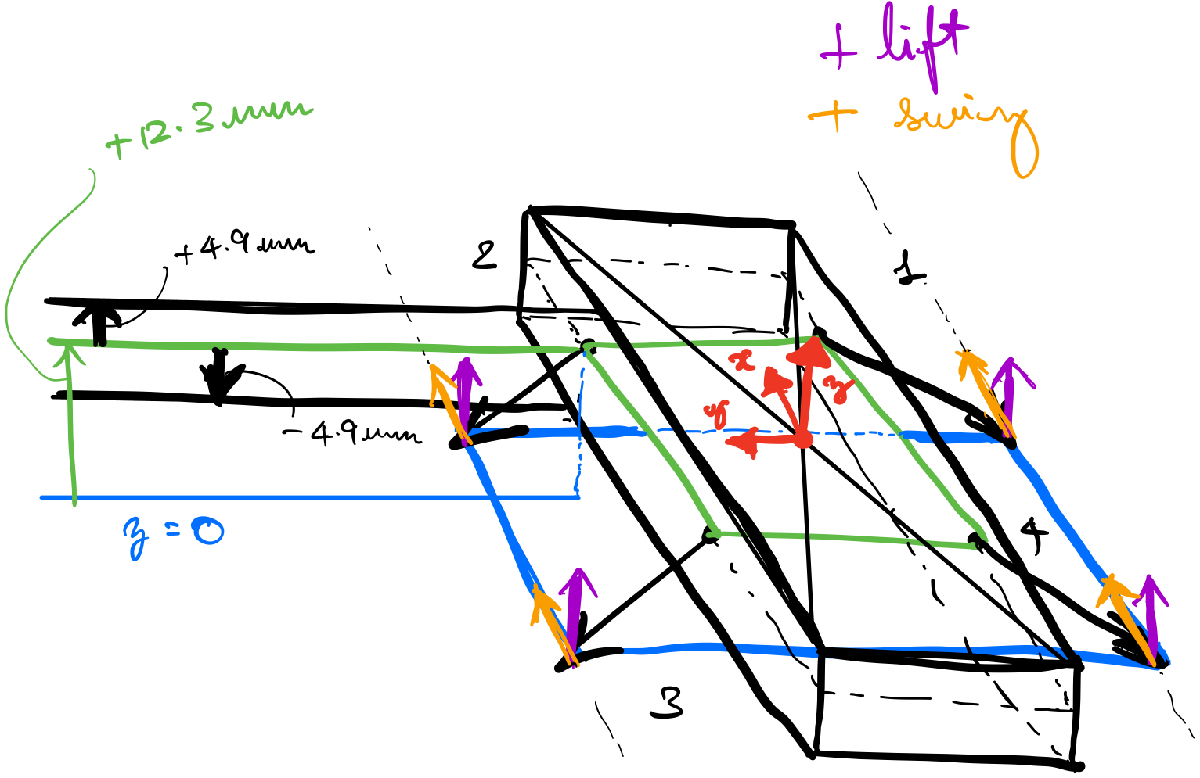

% z-change in HAMR6 with markers on (body center in the middle of the top plate in 2017 Ben Goldberg's: 10.1109/IROS.2017.8206249)
z_body2hipbox = [0, 0, -4.19];
z_body2bodyboundboxT = [0, 0, 0]; % top body bound box is at the body frame level
z_body2bodyboundboxB = [0, 0, -4.19*2];

% find the location of frame 1b hip-frame from the center of the robot-- translational sub-group of SE3
%%%%%%%%%% just h denotes SE2 transformations: ht translations, hR rotations
%%%%%%%%%% h3 denotes SE3 transformations: ht3 translations, hR3 rotations
%%%%%%%%%% small 'h' stands for vector form of se3/2 transformation, 'H' stands for the group action form of se3/2 transformation
h3_b__hip = boundbox2ht3transform(hip_bound) + repmat(z_body2hipbox, [size(hip_bound, 1), 1]); % repeat over rows
h3_b__1b = h3_b__hip(1, :);
h3_b__2b = h3_b__hip(2, :);
h3_b__3b = h3_b__hip(3, :);
h3_b__4b = h3_b__hip(4, :);

% find the location of the top and bottom bounding boxes
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% TOP
h3_b__bboundT = boundbox2ht3transform(bodywoleg_bound)+ repmat(z_body2bodyboundboxT, [size(bodywoleg_bound, 1), 1]);
h3_b__1cT = h3_b__bboundT(1, :);
h3_b__2cT = h3_b__bboundT(2, :);
h3_b__3cT = h3_b__bboundT(3, :);
h3_b__4cT = h3_b__bboundT(4, :);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% BOT
h3_b__bboundB = boundbox2ht3transform(bodywoleg_bound)+ repmat(z_body2bodyboundboxB, [size(bodywoleg_bound, 1), 1]);
h3_b__1cB = h3_b__bboundB(1, :);
h3_b__2cB = h3_b__bboundB(2, :);
h3_b__3cB = h3_b__bboundB(3, :);
h3_b__4cB = h3_b__bboundB(4, :);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% JOIN (add links to join the top and bottom sides)
h3_b__bboundB2T = h3_b__bboundT - h3_b__bboundB;

% Finally, let's find the transformations to these frames (no rotations since they all have the same orientation as the body frame)
% SE3 transformations for the hip frame ##############################################################
H3_b__hip = t_SE3(h3_b__hip); 
H3_b__1b = H3_b__hip{1};
H3_b__2b = H3_b__hip{2};
H3_b__3b = H3_b__hip{3};
H3_b__4b = H3_b__hip{4};
% SE3 transformations for the top bounding box #######################################################
H3_b__bboundT = t_SE3(h3_b__bboundT); 
H3_b__1cT = H3_b__bboundT{1};
H3_b__2cT = H3_b__bboundT{2};
H3_b__3cT = H3_b__bboundT{3};
H3_b__4cT = H3_b__bboundT{4};
% SE3 transformations for the bot bounding box #######################################################
H3_b__bboundB = t_SE3(h3_b__bboundB);
H3_b__1cB = H3_b__bboundB{1};
H3_b__2cB = H3_b__bboundB{2};
H3_b__3cB = H3_b__bboundB{3};
H3_b__4cB = H3_b__bboundB{4};

Let's plot what we have so far and visualize it from a few different view points.

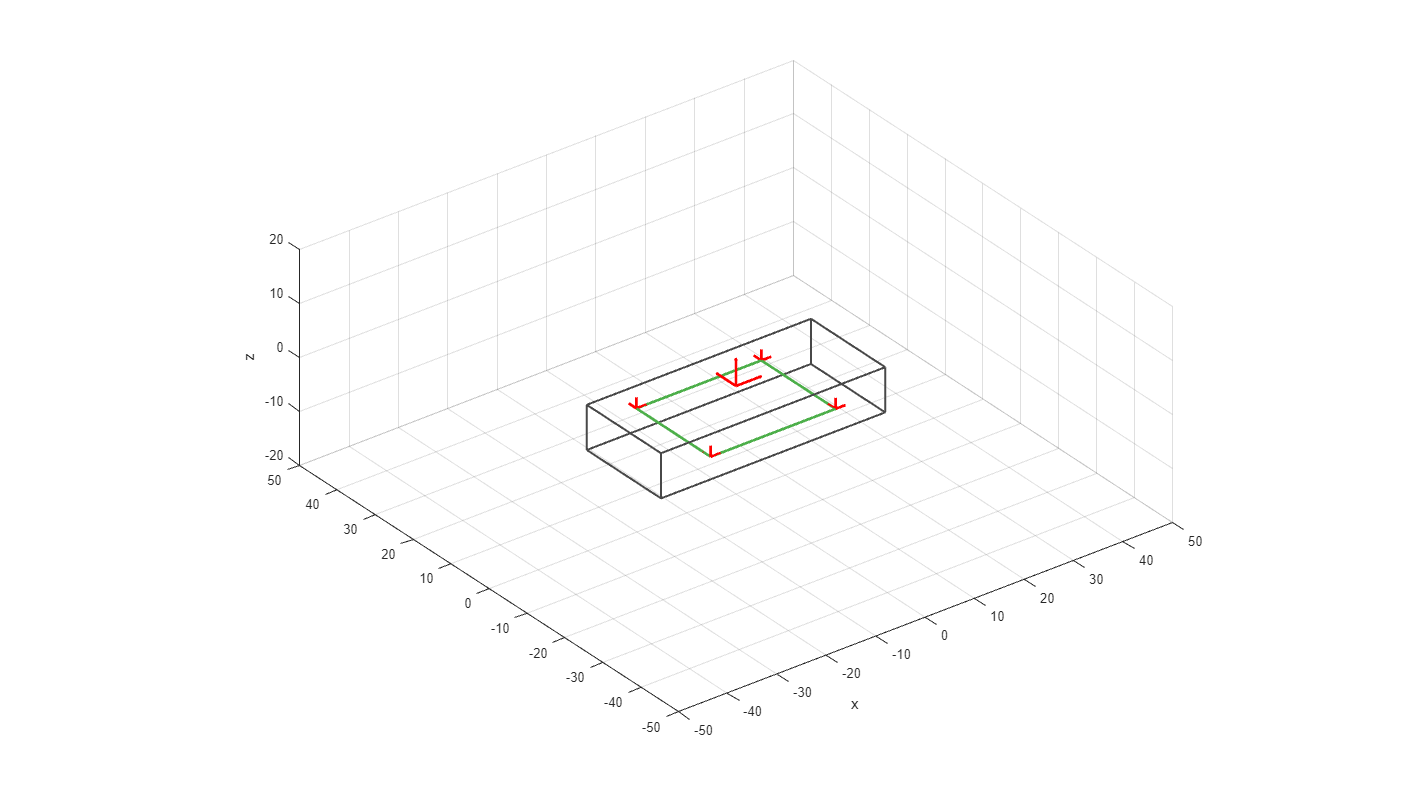

figure('units','pixels','position',[0 0 1920 1080],'Color','w')
% plot the hip bound box %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
quiver3(h3_b__hip(:, 1), h3_b__hip(:, 2), h3_b__hip(:, 3), hip_bound(:, 1), hip_bound(:, 2), hip_bound(:, 3),...
    'LineWidth', 2, 'Color', [77, 175, 74]/255, 'AutoScale', 'off', 'ShowArrowHead', 'off');
% set some props %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
hold on; view(-37.5, 30); axis square equal; axis([-50 50 -50 50 -20 20]); xlabel('x'); zlabel('y'); zlabel('z');
% plot the body bound boxes and complete it %%%%%%%%%%%%%%%%%%%
quiver3(h3_b__bboundT(:, 1), h3_b__bboundT(:, 2), h3_b__bboundT(:, 3), bodywoleg_bound(:, 1), bodywoleg_bound(:, 2), bodywoleg_bound(:, 3),...
    'LineWidth', 1.5, 'Color', [72, 72, 72]/255, 'AutoScale', 'off', 'ShowArrowHead', 'off'); % top box
quiver3(h3_b__bboundB(:, 1), h3_b__bboundB(:, 2), h3_b__bboundB(:, 3), bodywoleg_bound(:, 1), bodywoleg_bound(:, 2), bodywoleg_bound(:, 3),...
    'LineWidth', 1.5, 'Color', [72, 72, 72]/255, 'AutoScale', 'off', 'ShowArrowHead', 'off'); % bottom box
quiver3(h3_b__bboundB(:, 1), h3_b__bboundB(:, 2), h3_b__bboundB(:, 3), h3_b__bboundB2T(:, 1), h3_b__bboundB2T(:, 2), h3_b__bboundB2T(:, 3),...
    'LineWidth', 1.5, 'Color', [72, 72, 72]/255, 'AutoScale', 'off', 'ShowArrowHead', 'off'); % connection
% plot the body frame %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
quiver3(zeros(3,1), zeros(3,1), zeros(3,1), [5, 0, 0]', [0, 5, 0]', [0, 0, 5]', 'LineWidth', 2, 'Color', 'r', 'AutoScale', 'off');
% plot the hip frames %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
for i = 1:size(h3_b__hip, 1)
    quiver3(h3_b__hip(i,1)*ones(3,1), h3_b__hip(i,2)*ones(3,1), h3_b__hip(i,3)*ones(3,1), [2, 0, 0]', [0, 2, 0]', [0, 0, 2]',...
    'LineWidth', 2, 'Color', 'r', 'AutoScale', 'off');
end

### Full SE(3) transformations in body frame

Let's model the legs about the SFB using lift and swing angles inputs-- the positive lift and swing angles are shown in the 3D reconstruction sketch.

Thus, the leg transformations from the SFB are characterized by a rotation along Z for a swing angle ($-\alpha$ for the left side of the body and $\alpha$  for he right side of the body) followed by a rotation along Y for a lift angle ($\beta$ for the left side of the body and $-\beta$  for he right side of the body)-- let's call this frame 1bR (for rotated 1b frame).

syms alpha_1 beta_1 alpha_2 beta_2 alpha_3 beta_3 alpha_4 beta_4 real
h3_ib__ibR_z = [alpha_1, -alpha_2, -alpha_3, alpha_4]'; h3_ib__ibR_y = [-beta_1, beta_2, beta_3, -beta_4]';
H3_ib__ibR_z = rotz_SE3(h3_ib__ibR_z); H3_ib__ibR_y = roty_SE3(h3_ib__ibR_y);
H3_1b__1bR = simplify(H3_ib__ibR_z{1}*H3_ib__ibR_y{1});
H3_2b__2bR = simplify(H3_ib__ibR_z{2}*H3_ib__ibR_y{2});
H3_3b__3bR = simplify(H3_ib__ibR_z{3}*H3_ib__ibR_y{3});
H3_4b__4bR = simplify(H3_ib__ibR_z{4}*H3_ib__ibR_y{4});

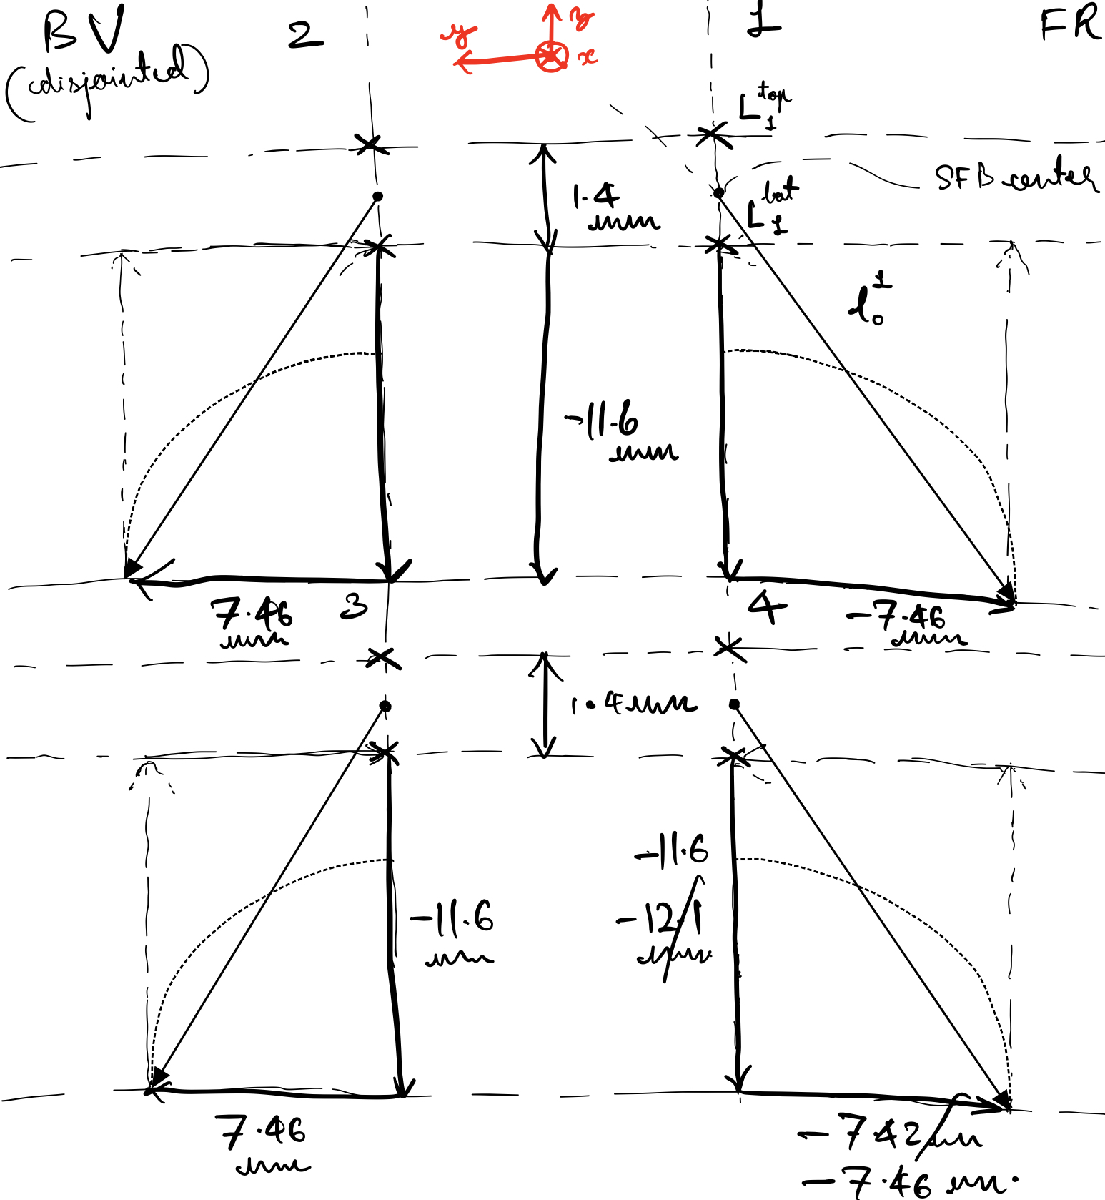

Then, we translate along the directions specified in the figure above-- this will give us the foot-tip frames.

h3_1bR__1 = [0, -7.46, -11.6];
h3_2bR__2 = [0, +7.46, -11.6];
h3_3bR__3 = [0, +7.46, -11.6];
h3_4bR__4 = [0, -7.46, -11.6];
H3_1bR__1 = t_SE3(h3_1bR__1);
H3_2bR__2 = t_SE3(h3_2bR__2);
H3_3bR__3 = t_SE3(h3_3bR__3);
H3_4bR__4 = t_SE3(h3_4bR__4);
% Compute the complete transformation from hip-frame to the foot
H3_1b__1 = simplify(H3_1b__1bR*H3_1bR__1)

$$H3\_1b\_\_1 = \left(\begin{array}{cccc} \cos\left(\alpha -\beta \right) & -\sin\left(\alpha -\beta \right) & 0 & \frac{373\,\sin\left(\alpha -\beta \right)}{50}\\ \sin\left(\alpha -\beta \right) & \cos\left(\alpha -\beta \right) & 0 & -\frac{373\,\cos\left(\alpha -\beta \right)}{50}\\ 0 & 0 & 1 & -\frac{58}{5}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

H3_2b__2 = simplify(H3_2b__2bR*H3_2bR__2)

$$H3\_2b\_\_2 = \left(\begin{array}{cccc} \cos\left(\alpha -\beta \right) & \sin\left(\alpha -\beta \right) & 0 & \frac{373\,\sin\left(\alpha -\beta \right)}{50}\\ -\sin\left(\alpha -\beta \right) & \cos\left(\alpha -\beta \right) & 0 & \frac{373\,\cos\left(\alpha -\beta \right)}{50}\\ 0 & 0 & 1 & -\frac{58}{5}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

H3_3b__3 = simplify(H3_3b__3bR*H3_3bR__3)

$$H3\_3b\_\_3 = \left(\begin{array}{cccc} \cos\left(\alpha -\beta \right) & \sin\left(\alpha -\beta \right) & 0 & \frac{373\,\sin\left(\alpha -\beta \right)}{50}\\ -\sin\left(\alpha -\beta \right) & \cos\left(\alpha -\beta \right) & 0 & \frac{373\,\cos\left(\alpha -\beta \right)}{50}\\ 0 & 0 & 1 & -\frac{58}{5}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

H3_4b__4 = simplify(H3_4b__4bR*H3_4bR__4)

$$H3\_4b\_\_4 = \left(\begin{array}{cccc} \cos\left(\alpha -\beta \right) & -\sin\left(\alpha -\beta \right) & 0 & \frac{373\,\sin\left(\alpha -\beta \right)}{50}\\ \sin\left(\alpha -\beta \right) & \cos\left(\alpha -\beta \right) & 0 & -\frac{373\,\cos\left(\alpha -\beta \right)}{50}\\ 0 & 0 & 1 & -\frac{58}{5}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

% Let's compute the transforms from the body as well
H3_b__1 = simplify(H3_b__1b*H3_1b__1)

$$H3\_b\_\_1 = \left(\begin{array}{cccc} \cos\left(\alpha -\beta \right) & -\sin\left(\alpha -\beta \right) & 0 & \frac{373\,\sin\left(\alpha -\beta \right)}{50}+\frac{253}{20}\\ \sin\left(\alpha -\beta \right) & \cos\left(\alpha -\beta \right) & 0 & -\frac{373\,\cos\left(\alpha -\beta \right)}{50}-\frac{49}{5}\\ 0 & 0 & 1 & -\frac{1579}{100}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

H3_b__2 = simplify(H3_b__2b*H3_2b__2)

$$H3\_b\_\_2 = \left(\begin{array}{cccc} \cos\left(\alpha -\beta \right) & \sin\left(\alpha -\beta \right) & 0 & \frac{373\,\sin\left(\alpha -\beta \right)}{50}+\frac{253}{20}\\ -\sin\left(\alpha -\beta \right) & \cos\left(\alpha -\beta \right) & 0 & \frac{373\,\cos\left(\alpha -\beta \right)}{50}+\frac{49}{5}\\ 0 & 0 & 1 & -\frac{1579}{100}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

H3_b__3 = simplify(H3_b__3b*H3_3b__3)

$$H3\_b\_\_3 = \left(\begin{array}{cccc} \cos\left(\alpha -\beta \right) & \sin\left(\alpha -\beta \right) & 0 & \frac{373\,\sin\left(\alpha -\beta \right)}{50}-\frac{253}{20}\\ -\sin\left(\alpha -\beta \right) & \cos\left(\alpha -\beta \right) & 0 & \frac{373\,\cos\left(\alpha -\beta \right)}{50}+\frac{49}{5}\\ 0 & 0 & 1 & -\frac{1579}{100}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

H3_b__4 = simplify(H3_b__4b*H3_4b__4)

$$H3\_b\_\_4 = \left(\begin{array}{cccc} \cos\left(\alpha -\beta \right) & -\sin\left(\alpha -\beta \right) & 0 & \frac{373\,\sin\left(\alpha -\beta \right)}{50}-\frac{253}{20}\\ \sin\left(\alpha -\beta \right) & \cos\left(\alpha -\beta \right) & 0 & -\frac{373\,\cos\left(\alpha -\beta \right)}{50}-\frac{49}{5}\\ 0 & 0 & 1 & -\frac{1579}{100}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

% Convert these to functions and store it in a struct for later access
fH3_b__1 = matlabFunction(H3_b__1, 'Vars', [alpha_1 beta_1]);
fH3_b__2 = matlabFunction(H3_b__2, 'Vars', [alpha_2 beta_2]);
fH3_b__3 = matlabFunction(H3_b__3, 'Vars', [alpha_3 beta_3]);
fH3_b__4 = matlabFunction(H3_b__4, 'Vars', [alpha_4 beta_4]);

% Let's compute the full-jacobian for each leg using the adjoint inverse operation

% Initialize the struct and start storing computed quantities
HAMR_6_SE3 = [];
HAMR_6_SE3.transforms = [];
HAMR_6_SE3.transforms.num = [];
HAMR_6_SE3.transforms.sym = [];
HAMR_6_SE3.transforms.fun = [];
% % % % % % % % % % % % % % % % % % HAMR_6_SE3.transforms.sym.H3_b__1 = H3_b__1;                % MANUAL WAY-- DEPRECATED
% % % % % % % % % % % % % % % % % % HAMR_6_SE3.transforms.sym.H3_b__2 = H3_b__2;
% % % % % % % % % % % % % % % % % % HAMR_6_SE3.transforms.sym.H3_b__3 = H3_b__3;
% % % % % % % % % % % % % % % % % % HAMR_6_SE3.transforms.sym.H3_b__4 = H3_b__4;
% % % % % % % % % % % % % % % % % % HAMR_6_SE3.transforms.fun.fH3_b__1 = fH3_b__1;
% % % % % % % % % % % % % % % % % % HAMR_6_SE3.transforms.fun.fH3_b__2 = fH3_b__2;
% % % % % % % % % % % % % % % % % % HAMR_6_SE3.transforms.fun.fH3_b__3 = fH3_b__3;
% % % % % % % % % % % % % % % % % % HAMR_6_SE3.transforms.fun.fH3_b__4 = fH3_b__4;
% % % % % % % % % % % % % % % % % % HAMR_6_SE3.transforms.sym.H3_1b__1 = H3_1b__1;
% % % % % % % % % % % % % % % % % % HAMR_6_SE3.transforms.sym.H3_2b__2 = H3_2b__2;
% % % % % % % % % % % % % % % % % % HAMR_6_SE3.transforms.sym.H3_3b__3 = H3_3b__3;
% % % % % % % % % % % % % % % % % % HAMR_6_SE3.transforms.sym.H3_4b__4 = H3_4b__4;
% % % % % % % % % % % % % % % % % % HAMR_6_SE3.transforms.sym.H3_1bR__1 = H3_1bR__1;
% % % % % % % % % % % % % % % % % % HAMR_6_SE3.transforms.sym.H3_2bR__2 = H3_2bR__2;
% % % % % % % % % % % % % % % % % % HAMR_6_SE3.transforms.sym.H3_3bR__3 = H3_3bR__3;
% % % % % % % % % % % % % % % % % % HAMR_6_SE3.transforms.sym.H3_4bR__4 = H3_4bR__4;
% % % % % % % % % % % % % % % % % % HAMR_6_SE3.transforms.sym.H3_1b__1bR = H3_1b__1bR;
% % % % % % % % % % % % % % % % % % HAMR_6_SE3.transforms.sym.H3_2b__2bR = H3_2b__2bR;
% % % % % % % % % % % % % % % % % % HAMR_6_SE3.transforms.sym.H3_3b__3bR = H3_3b__3bR;
% % % % % % % % % % % % % % % % % % HAMR_6_SE3.transforms.sym.H3_4b__4bR = H3_4b__4bR;
% % % % % % % % % % % % % % % % % % HAMR_6_SE3.transforms.num.H3_b__1cB = H3_b__1cB;
% % % % % % % % % % % % % % % % % % HAMR_6_SE3.transforms.num.H3_b__2cB = H3_b__2cB;
% % % % % % % % % % % % % % % % % % HAMR_6_SE3.transforms.num.H3_b__3cB = H3_b__3cB;
% % % % % % % % % % % % % % % % % % HAMR_6_SE3.transforms.num.H3_b__4cB = H3_b__4cB;
% % % % % % % % % % % % % % % % % % HAMR_6_SE3.transforms.num.H3_b__1cT = H3_b__1cT;
% % % % % % % % % % % % % % % % % % HAMR_6_SE3.transforms.num.H3_b__2cT = H3_b__2cT;
% % % % % % % % % % % % % % % % % % HAMR_6_SE3.transforms.num.H3_b__3cT = H3_b__3cT;
% % % % % % % % % % % % % % % % % % HAMR_6_SE3.transforms.num.H3_b__4cT = H3_b__4cT;
% % % % % % % % % % % % % % % % % % HAMR_6_SE3.transforms.num.H3_b__1b = H3_b__1b;
% % % % % % % % % % % % % % % % % % HAMR_6_SE3.transforms.num.H3_b__2b = H3_b__2b;
% % % % % % % % % % % % % % % % % % HAMR_6_SE3.transforms.num.H3_b__3b = H3_b__3b;
% % % % % % % % % % % % % % % % % % HAMR_6_SE3.transforms.num.H3_b__4b = H3_b__4b;

% Iterate and store everything to the strcture you desire
for i = 1:4
    HAMR_6_SE3.transforms.num.(['H3_b__', num2str(i), 'b']) = eval(['H3_b__', num2str(i), 'b']);
    HAMR_6_SE3.transforms.num.(['H3_b__', num2str(i), 'cT']) = eval(['H3_b__', num2str(i), 'cT']);
    HAMR_6_SE3.transforms.num.(['H3_b__', num2str(i), 'cB']) = eval(['H3_b__', num2str(i), 'cB']);
    HAMR_6_SE3.transforms.sym.(['H3_' num2str(i) 'b__', num2str(i), 'bR']) = eval(['H3_' num2str(i) 'b__', num2str(i), 'bR']);
    HAMR_6_SE3.transforms.sym.(['H3_' num2str(i) 'bR__', num2str(i)]) = eval(['H3_' num2str(i) 'bR__', num2str(i)]);
    HAMR_6_SE3.transforms.sym.(['H3_' num2str(i) 'b__', num2str(i)]) = eval(['H3_' num2str(i) 'b__', num2str(i)]);
    HAMR_6_SE3.transforms.sym.(['H3_b__', num2str(i)]) = eval(['H3_b__', num2str(i)]);
    HAMR_6_SE3.transforms.sym.(['fH3_b__', num2str(i)]) = eval(['fH3_b__', num2str(i)]);
end
